Load data

dataInputraw = load("pricevolumedata.mat") ;

dataInput = dataCleaningFcn_v2(dataInputraw)

dataInput = struct with fields:
    closepriceTT: [2930×665 timetable]
     highpriceTT: [2930×665 timetable]
      indexclean: [2930×6 timetable]
      lowpriceTT: [2930×665 timetable]
     openpriceTT: [2930×665 timetable]
        volumeTT: [2930×665 timetable]



openpriceTT     = dataInput.openpriceTT ;
highpriceTT     = dataInput.highpriceTT ;
lowpriceTT      = dataInput.lowpriceTT ;
closepriceTT    = dataInput.closepriceTT ;
volumeTT        = dataInput.volumeTT ;

clear dataInputraw

Define walk window dataset

% lookback upper bound
lookbackUB = 250;

% Number of step for training datastasket
nstepTrain = 100;

% Number of step for testing dataset
nstepTest = 10;
% Number of step per walk dataset
nstepIST = lookbackUB + nstepTrain;
nstepOST = nstepTest;

% Number of walk for the whole walk forwad
nWalk = 12 ;
nstepWalk = nWalk*nstepOST + nstepIST;

% Number of rows in raw data
rowsData = size (closepriceTT,1) ;
% dataSet.openpriceTT = openpriceTT ;
% dataSet.highpriceTT = highpriceTT ;
% dataSet.lowpriceTT = lowpriceTT ;
% dataSet.closepriceTT = closepriceTT ;
% dataSet.volumeTT = volumeTT ;

Walk forward 

startTimer = tic ; 

nvars = 11 ; % number variables in optimParams to be optimizeds

% Preallocate
T = repmat (table(zeros(nWalk,1)),1,2+nvars)  ;
tableHeader = {'iteration', 'optimEndDate', 'volumeMAtreshold',...
               'volumeMAlookback', 'valueThreshold', 'valueLookback',...
               'volumeValueBufferDays', 'priceRetLowCloseThresh', 'priceMAThreshold',...
               'priceMAlookback', 'priceVolumeValueBufferDays',...
               'cutlossLookback', 'cutlosspct'} ;
T.Properties.VariableNames = tableHeader ;

timCOlumn = table(transpose ((datetime(2017,11,1:nWalk)))) ;
timCOlumn.Properties.VariableNames = {'optimEndDate'};

optimParamsTable = [T(:,1) timCOlumn(:,1) T(:,3:13) ];


i = 1

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    119   124     6     3     4    12   113    10     5     2     6


fval = -119.5330

exitflag = 0

outpt = struct with fields:
        elapsedtime: 258.9668
          funccount: 300
    constrviolation: 0
               ineq: [-0.0833 -5.6710 0 -0.2000 -0.3450]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 259.2875

optimParams_i =    119   124     6     3     4    12   113    10     5     2     6


i = 2

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    130    95    13     4     2     1   118    28     4     3     6


fval = -33.2194

exitflag = 0

outpt = struct with fields:
        elapsedtime: 239.8387
          funccount: 300
    constrviolation: 0
               ineq: [-0.0361 -5.0666 0 -0.1965 -0.2666]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 239.9638

optimParams_i =    130    95    13     4     2     1   118    28     4     3     6


i = 3

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    146    85     5     5     8    14   110    18     5     3     7


fval = -110.9833

exitflag = 0

outpt = struct with fields:
        elapsedtime: 257.0413
          funccount: 300
    constrviolation: 0
               ineq: [-0.0682 -5.6783 0 -0.1339 -0.2839]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 257.0761

optimParams_i =    146    85     5     5     8    14   110    18     5     3     7


i = 4

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    244    90     7     4     2     2   124    25     3     3     7


fval = -69.0809

exitflag = 0

outpt = struct with fields:
        elapsedtime: 200.3029
          funccount: 300
    constrviolation: 0
               ineq: [-0.0779 -5.4015 0 -0.1692 -0.3192]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 200.3222

optimParams_i =    244    90     7     4     2     2   124    25     3     3     7


i = 5

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     72    99     5     3     6     7   118    20     5     2     5


fval = -142.2765

exitflag = 0

outpt = struct with fields:
        elapsedtime: 208.0594
          funccount: 300
    constrviolation: 0
               ineq: [-0.0668 -5.9678 0 -0.1968 -0.3468]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 208.0819

optimParams_i =     72    99     5     3     6     7   118    20     5     2     5


i = 6

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    147   142     5     3     5    11   121    29     5     2     4


fval = -122.3968

exitflag = 0

outpt = struct with fields:
        elapsedtime: 256.0998
          funccount: 300
    constrviolation: 0
               ineq: [-0.0803 -5.6446 0 -0.2000 -0.3500]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 256.1156

optimParams_i =    147   142     5     3     5    11   121    29     5     2     4


i = 7

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    149   148     5     3     2     3   125    27     4     3     7


fval = -80.8126

exitflag = 0

outpt = struct with fields:
        elapsedtime: 198.1789
          funccount: 300
    constrviolation: 0
               ineq: [-0.0753 -6.0282 0 -0.2000 -0.3500]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 198.1912

optimParams_i =    149   148     5     3     2     3   125    27     4     3     7


i = 8

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    137    59     5     3     7    12   117     7     5     2     7


fval = -326.7473

exitflag = 0

outpt = struct with fields:
        elapsedtime: 209.3827
          funccount: 300
    constrviolation: 0
               ineq: [-0.0436 -6.9095 0 -0.1817 -0.3317]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 209.4077

optimParams_i =    137    59     5     3     7    12   117     7     5     2     7


i = 9

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    249   119     5     3    10    11   119    20     4     3     7


fval = -312.9177

exitflag = 0

outpt = struct with fields:
        elapsedtime: 169.1154
          funccount: 300
    constrviolation: 0
               ineq: [-0.0594 -6.5627 0 -0.2000 -0.3500]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 169.1302

optimParams_i =    249   119     5     3    10    11   119    20     4     3     7


i = 10

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =     72    53     5     3    10    15   118    23     4     3     7


fval = -360.6366

exitflag = 0

outpt = struct with fields:
        elapsedtime: 216.3763
          funccount: 300
    constrviolation: 0
               ineq: [-0.0745 -6.9849 0 -0.2000 -0.3500]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 216.3892

optimParams_i =     72    53     5     3    10    15   118    23     4     3     7


i = 11

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    134    61     5     3     3    12   117     7     5     2     7


fval = -443.3493

exitflag = 0

outpt = struct with fields:
        elapsedtime: 191.4239
          funccount: 300
    constrviolation: 0
               ineq: [-0.0436 -6.8620 0 -0.1989 -0.3489]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 191.4356

optimParams_i =    134    61     5     3     3    12   117     7     5     2     7


i = 12

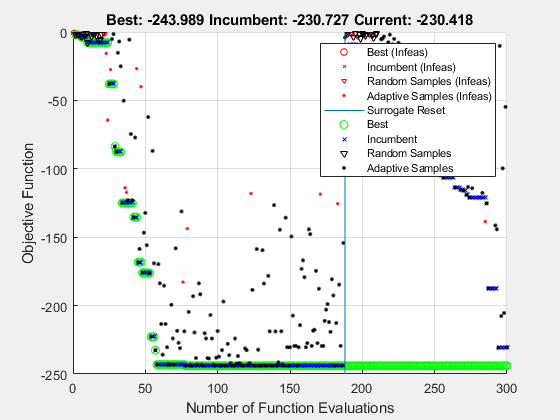

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


sol =    148    81     5     3     8    15    74     8     4     3     6


fval = -243.9888

exitflag = 0

outpt = struct with fields:
        elapsedtime: 210.5487
          funccount: 300
    constrviolation: 0
               ineq: [-0.0515 -6.2720 0 -0.1762 -0.3262]
           rngstate: [1×1 struct]
            message: 'surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'


endTime = 210.5645

optimParams_i =    148    81     5     3     8    15    74     8     4     3     6


for i = 1:nWalk
    i
    % steps per walk
    OSTend_i = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Define data set per walk
    % ISTdataSet
    ISTdataSet_i.openpriceTT    = openpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.highpriceTT    = highpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.lowpriceTT     = lowpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.closepriceTT   = closepriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.volumeTT       = volumeTT(ISTstart_i:ISTend_i,:) ;
    
    % Optimize optimParams per walk
    startOptimPoint = size(ISTdataSet_i.openpriceTT,1) - nstepTrain;
    
    optimParams_i = optimParamsFcn_v5 (ISTdataSet_i, startOptimPoint) 

    % Save optimparams per walk
    timeColumn = ISTdataSet_i.openpriceTT.Time ;
    timeISTend_i = datetime(timeColumn(end,:),'InputFormat','yyyy-MM-dd') ;
    
    optimParamsTable(i,1).Variables = i ;
    optimParamsTable(i,2).Variables = timeISTend_i ;
    optimParamsTable(i,3:13).Variables = optimParams_i ;

end


EndTimer = toc(startTimer)  

EndTimer = 2.6167e+03

timehours = EndTimer/(60*60)

timehours = 0.7269

Walk forward on optimizaed parameters in each walk

% Preallocate OSTportDailyRetTT 
% OSTportDailyRetTT = repmat(openpriceTT (1,1),nWalk*nstepOST,1) ;
OSTportDailyRetTT = openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

% Preallocate netDailyRetperSymTT
% OSTnetDailyRetperSymTT = repmat(closepriceTT (1,:), nWalk*nstepOST,1) ;
OSTnetDailyRetperSymTT = closepriceTT (1,:);
sym = OSTnetDailyRetperSymTT.Properties.VariableNames ;
sym = eraseBetween (sym, 5,10) ;
OSTnetDailyRetperSymTT.Properties.VariableNames  = sym ;

% Preallocate tradingSignalTT 
OSTtradingSignalTT = OSTnetDailyRetperSymTT ;

for i = 1:nWalk
    
    % steps per walk
    OSTend_i    = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i  = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Params i
    paramsInput_i   = optimParamsTable(i,3:13).Variables;
    maxlookback     = max (paramsInput_i) ;
    
    % Define dataset
    % OSTdataSet
    OSTdataSet_i.openpriceTT    = openpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.highpriceTT    = highpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.lowpriceTT     = lowpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.closepriceTT   = closepriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.volumeTT       = volumeTT(OSTstart_i-maxlookback:OSTend_i,:) ;

    % Calculate portCumRet in OST
    tradingSignalTT_i = tradingSignalFcnVectorized_v1 (paramsInput_i, OSTdataSet_i) ;
    [portDailyRetTT_i, netDailyRetperSymTT_i] = tradingBacktestFcn_v2 (tradingSignalTT_i, OSTdataSet_i);
        
    % Concatenate OSTportDailyRetTT
    OSTnetDailyRetperSymTT_i = netDailyRetperSymTT_i(end-nstepOST+1:end,:) ;
    OSTnetDailyRetperSymTT = [OSTnetDailyRetperSymTT; OSTnetDailyRetperSymTT_i ] ;
    
    % Concatenate OSTportDailyRetTT
    portDailyRetTT_i.Properties.VariableNames = OSTportDailyRetTT.Properties.VariableNames  ;
    OSTportDailyRetTT_i = portDailyRetTT_i(end-nstepOST+1:end,:) ;
    OSTportDailyRetTT = [OSTportDailyRetTT; OSTportDailyRetTT_i]  ;

    % Concatenate tradingSignalTT
    OSTtradingSignalTT_i = tradingSignalTT_i(end-nstepOST+1:end,:) ;
    OSTtradingSignalTT = [OSTtradingSignalTT; OSTtradingSignalTT_i] ;

end

OSTtradingSignalTT (1,:)       = []

OSTtradingSignalTT = 120×665 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    <

OSTnetDailyRetperSymTT (1,:)   = []

OSTnetDailyRetperSymTT = 120×665 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI       ALDO        ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX

OSTportDailyRetTT (1,:)        = []

OSTportDailyRetTT = 120×1 timetable
       Time       OSTportDailyRet
    __________    _______________

    2021-04-27                0  
    2021-04-28         0.024667  
    2021-04-29         0.059305  
    2021-04-30         -0.02524  
    2021-05-03      -6.4481e-05  
    2021-05-04        0.0091604  
    2021-05-05        -0.023021  
    2021-05-06        -0.018158  
    2021-05-07        -0.015716  
    2021-05-10      -8.6743e-05  
    2021-05-11         0.014691  
    2021-05-17          0.01005  
    2021-05-18         0.073222  
    2021-05-19        0.0047083  
    2021-05-20        -0.028893  
    2021-05-21        0.0062308  


Analyze the results

plot chart animation

walk_i = 1

walkStart_i = 1

walkEnd_i = 10

walk_i = 2

walkStart_i = 11

walkEnd_i = 20

walk_i = 3

walkStart_i = 21

walkEnd_i = 30

walk_i = 4

walkStart_i = 31

walkEnd_i = 40

walk_i = 5

walkStart_i = 41

walkEnd_i = 50

walk_i = 6

walkStart_i = 51

walkEnd_i = 60

walk_i = 7

walkStart_i = 61

walkEnd_i = 70

walk_i = 8

walkStart_i = 71

walkEnd_i = 80

walk_i = 9

walkStart_i = 81

walkEnd_i = 90

walk_i = 10

walkStart_i = 91

walkEnd_i = 100

walk_i = 11

walkStart_i = 101

walkEnd_i = 110

walk_i = 12

walkStart_i = 111

walkEnd_i = 120

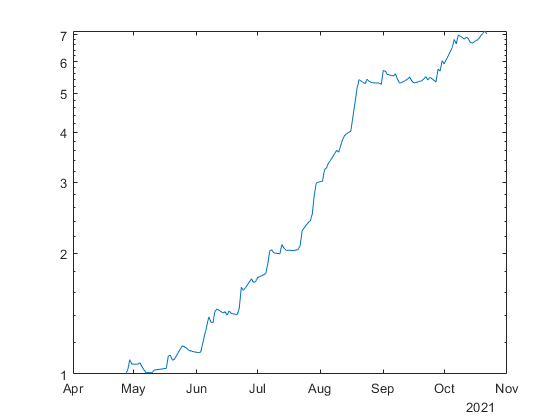

% Plot animated chart with pause or drawnow function
% Plot portCumRetTT    
% Plot animated chart with pause or drawnow function
for i = 1:nWalk
%     i = 2
    walk_i = i 

    walkStart_i = 1+ nstepOST*(i-1)
    walkEnd_i = walkStart_i + nstepOST-1
    OSTportDailyRetTT_i = OSTportDailyRetTT(1:walkEnd_i, :);
    
    OSTportCumRetTT = ret2tick (OSTportDailyRetTT_i) ;

    semilogy(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
%     plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
    drawnow 
    pause(4);

end

Statistics

% OSTportCumRetTT = ret2tick (OSTportDailyRetTT) ;
% 
% plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

% CAGR
timeVar = OSTportCumRetTT.Time ;
OSTportCumRet = OSTportCumRetTT.Variables ;
OSTportCumRetEnd = OSTportCumRet(end,:)

OSTportCumRetEnd = 7.0406

nYear = yearfrac (timeVar(1,:), timeVar(end,:))

nYear = 0.4877

CAGR = ((OSTportCumRet (end,:) / OSTportCumRet (1,:))^(1/nYear))-1

CAGR = 53.7115


% Drawdown
[MDD,MaxDDIndex] = maxdrawdown(OSTportCumRetTT.Variables) ;
MaxDD = MDD 

MaxDD = 0.0714

drawDownTime = timeVar(MaxDDIndex)

drawDownTime = 2×1 datetime array
   2021-04-29
   2021-05-10


Number signal daily

nDailySignal = sum (OSTtradingSignalTT.Variables,2)

nDailySignal =      0
     4
     6
     4
     2
     3
     5
     5
     6
     4


nDailySignalTT = OSTportCumRetTT

nDailySignalTT = 120×1 timetable
       Time       OSTportDailyRet
    __________    _______________

    2021-04-27             1     
    2021-04-28        1.0247     
    2021-04-29        1.0854     
    2021-04-30         1.058     
    2021-05-03         1.058     
    2021-05-04        1.0677     
    2021-05-05        1.0431     
    2021-05-06        1.0241     
    2021-05-07         1.008     
    2021-05-10         1.008     
    2021-05-11        1.0228     
    2021-05-17         1.033     
    2021-05-18        1.1087     
    2021-05-19        1.1139     
    2021-05-20        1.0817     
    2021-05-21        1.0885     


nDailySignalTT.Variables = nDailySignal

nDailySignalTT = 120×1 timetable
       Time       OSTportDailyRet
    __________    _______________

    2021-04-27           0       
    2021-04-28           4       
    2021-04-29           6       
    2021-04-30           4       
    2021-05-03           2       
    2021-05-04           3       
    2021-05-05           5       
    2021-05-06           5       
    2021-05-07           6       
    2021-05-10           4       
    2021-05-11           9       
    2021-05-17          11       
    2021-05-18           4       
    2021-05-19           8       
    2021-05-20           5       
    2021-05-21           2       


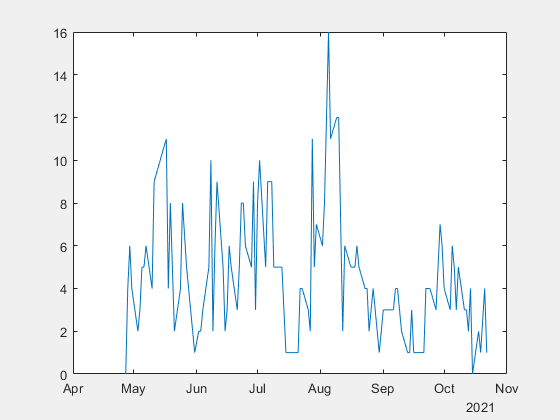


% plot daily signal
plot(nDailySignalTT.Time , nDailySignalTT.Variables )

Rank symbol based on cumulative return

symRank = rankSymbolsFcn (OSTnetDailyRetperSymTT);

symRank = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'BOLA'}       {[1.2648]}    
    {'REAL'}       {[1.1961]}    
    {'MLPL'}       {[1.1851]}    
    {'TECH'}       {[1.1527]}    
    {'BABP'}       {[1.1401]}    
    {'MSIN'}       {[1.1291]}    
    {'BSIM'}       {[1.0978]}    
    {'TOYS'}       {[1.0888]}    
    {'LMAS'}       {[1.0754]}    
    {'MMLP'}       {[1.0665]}    
    {'BUMI'}       {[1.0609]}    
    {'PRIM'}       {[1.0599]}    
    {'BCAP'}       {[1.0590]}    
    {'KIOS'}       {[1.0589]}    
    {'PANR'}       {[1.0550]}    
    {'WEHA'}       {[1.0543]}    


Discretionary

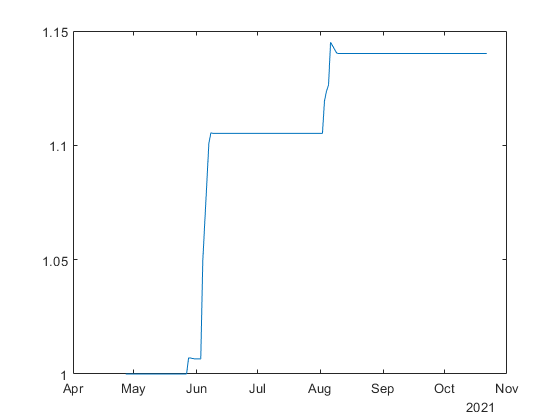

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.BABP)

Save optimParams to matfile

% Save optimParams to matfile
optimParams_filename = "optimParams.mat";
save (optimParams_filename , "optimParamsTable") 
